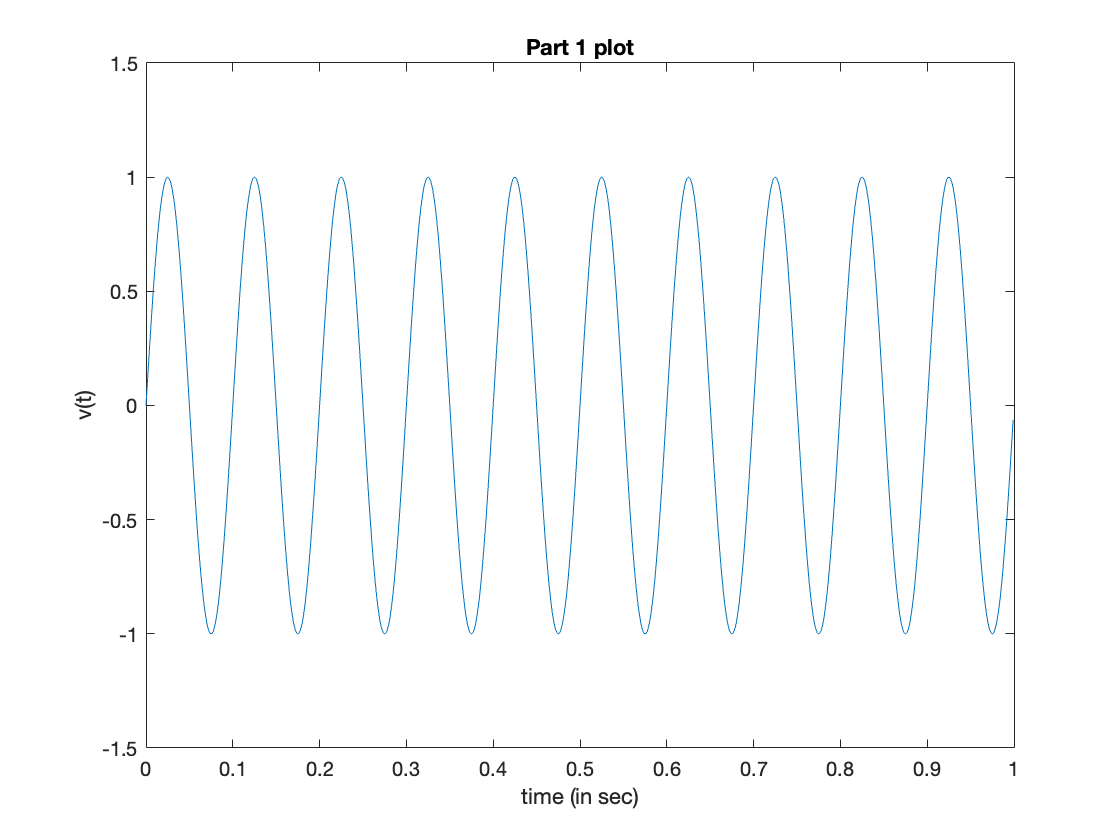

%%--------------------------------Part A ---------------------------------- 

%Sampling Frequency in Hz
Fs = 1000;

%Time vector in seconds
t = 0 : 1/Fs : 1 - 1/Fs;

%Frequency of the sine wave in Hz
fc = 10;

%sine wave generation
sinewav1 = sin(2*pi*fc*t);

%plotting
plot(t,sinewav1);
title("Part 1 plot");
xlabel("time (in sec)");
ylabel("v(t)");
ylim([-1.5 1.5]);

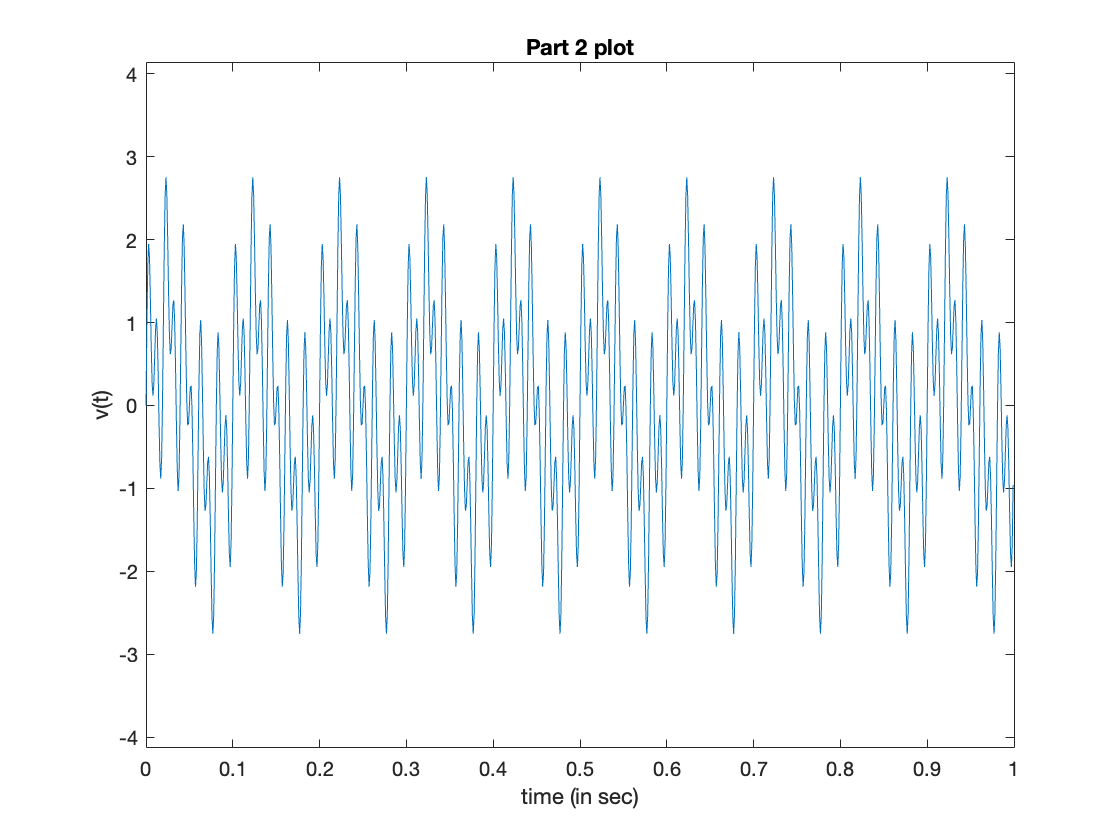

%%--------------------------------Part B ---------------------------------- 

%Time vector in seconds
t = 0 : 1/Fs : 1 - 1/Fs;

%Frequency of the sine waves in Hz
fc1 = 10;
fc2 = 50;
fc3 = 100;

%sine wave generation individual sine waves
sinewav1 = sin(2*pi*fc1*t);
sinewav2 = sin(2*pi*fc2*t);
sinewav3 = sin(2*pi*fc3*t);

%generating Multitone sine wave by superpostion of the above three waves
multitone = sinewav1 + sinewav2 + sinewav3;

%plotting
plot(t,multitone);
title("Part 2 plot");
xlabel("time (in sec)");
ylabel("v(t)");
ylim([-1.5*max(multitone) 1.5*max(multitone)]);

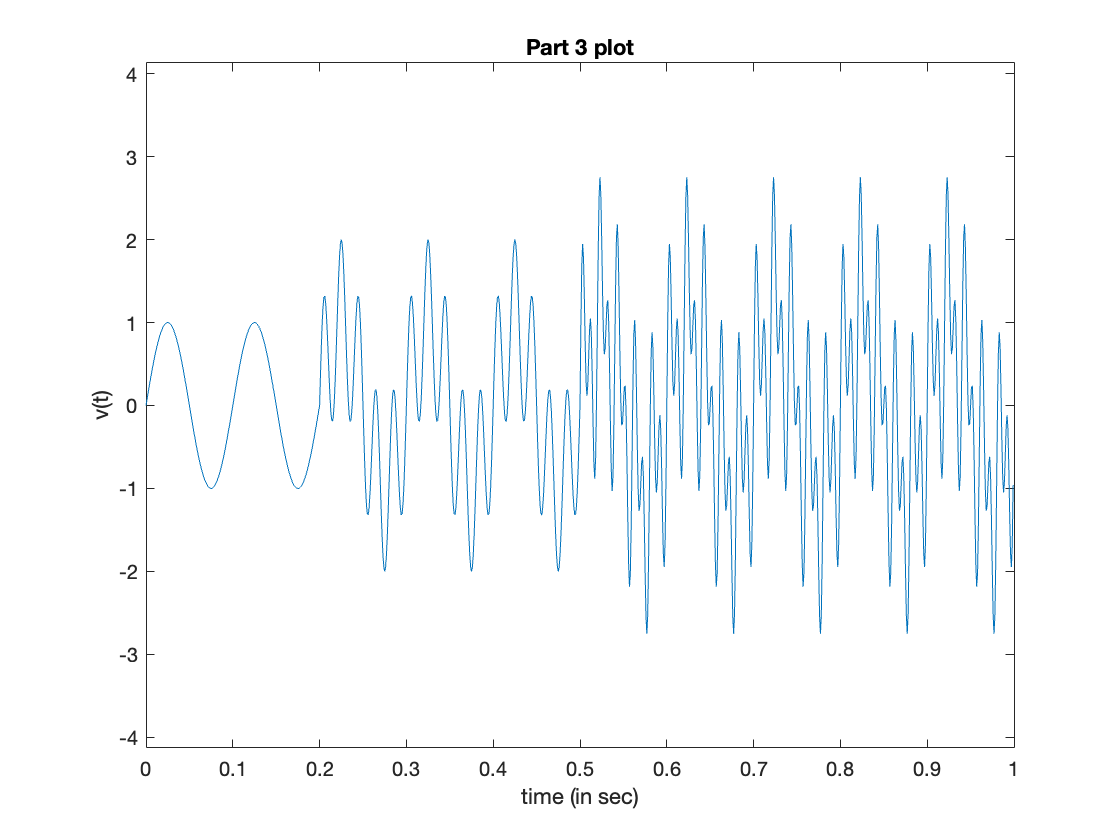

%%--------------------------------Part C ---------------------------------- 

% part a)

%Time vector in seconds
t = 0 : 1/Fs : 1 - 1/Fs;

%Frequency of the sine waves in Hz
fc1 = 10;
fc2 = 50;
fc3 = 100;

%sine wave generation individual sine waves

% (1) Sin(2𝛱*10t)    
sinewav1 = sin(2*pi*fc1*t);
% (2) Sin(2𝛱*50*t)   0.2 sec < t < 1 sec and 0 for 0 < t < 0.2 sec
sinewav2 = sin(2*pi*fc2*t);
sinewav2(1:0.2*Fs) = 0;

% (3) Sin(2𝛱*100*t)   0.5 sec < t < 1 sec and 0 for 0 < t < 0.5 sec
sinewav3 = sin(2*pi*fc3*t);
sinewav3(1:0.5*Fs) = 0;

%super-position of the three parts

nonStationary = sinewav1 + sinewav2 + sinewav3;

%plotting
plot(t,nonStationary);
title("Part 3 plot");
xlabel("time (in sec)");
ylabel("v(t)");
ylim([-1.5*max(nonStationary) 1.5*max(nonStationary)]);

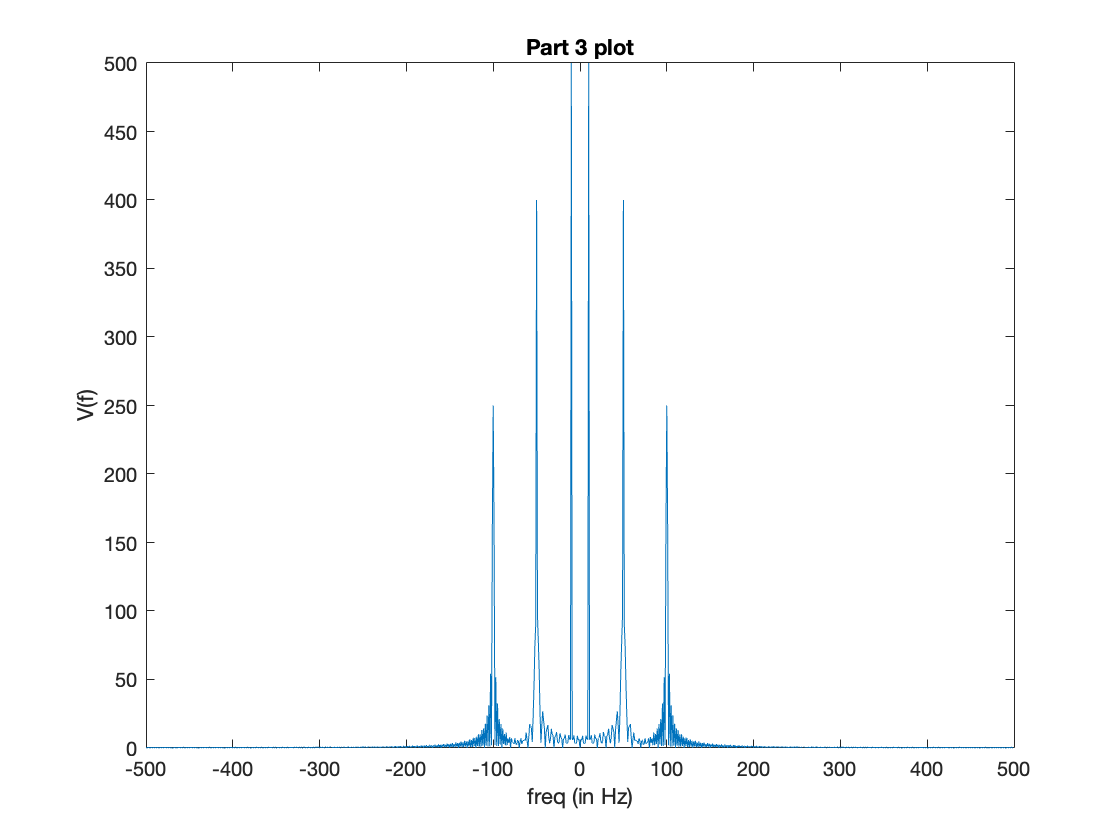

% part b) spectrum of the generated non stationary signal

fftFull = fftshift(fft(nonStationary));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fftFull);  

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1; 

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

%Plotting
plot(freq,abs(fftFull));
title("Part 3 plot");
xlabel("freq (in Hz)");
ylabel("V(f)");

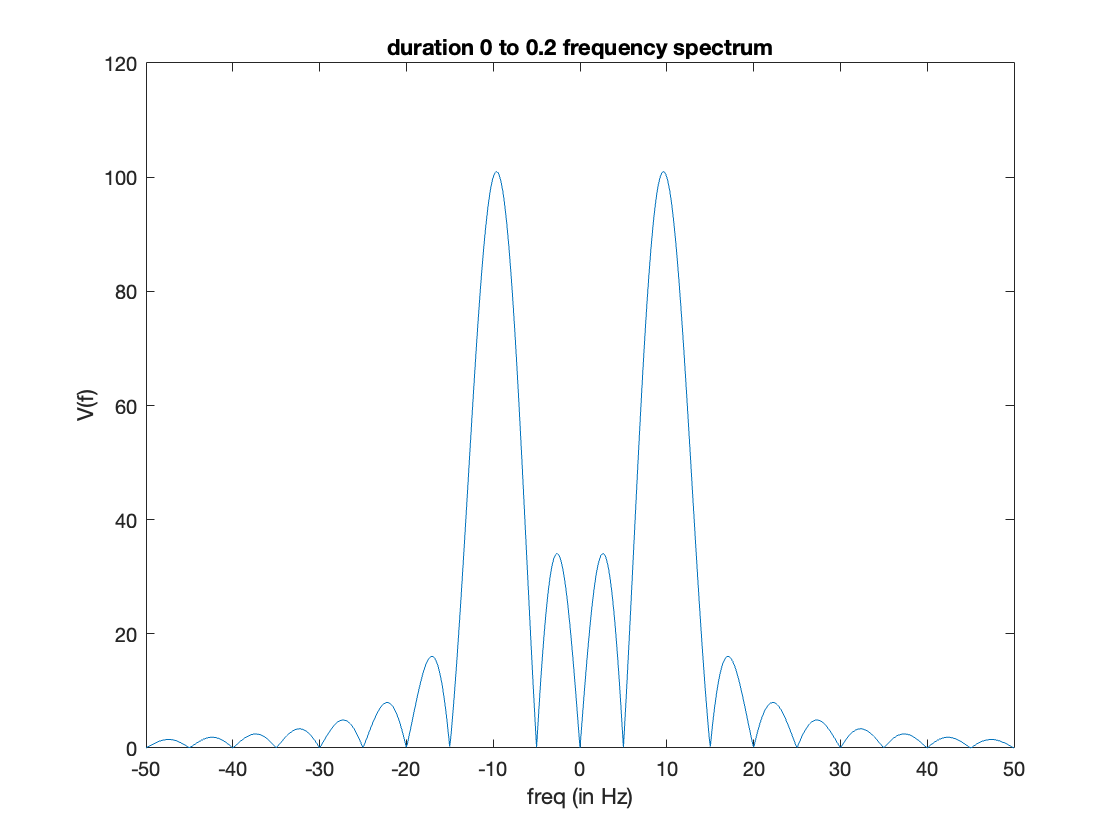

%individual frequency spectrum

% (1)for duration 0 to 0.2

fft1 = fftshift(fft(nonStationary(1:0.2*Fs),8192));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fft1);

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1;

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

plot(freq,abs(fft1));
title("duration 0 to 0.2 frequency spectrum");
xlabel("freq (in Hz)");
ylabel("V(f)");
xlim([-50,50]);

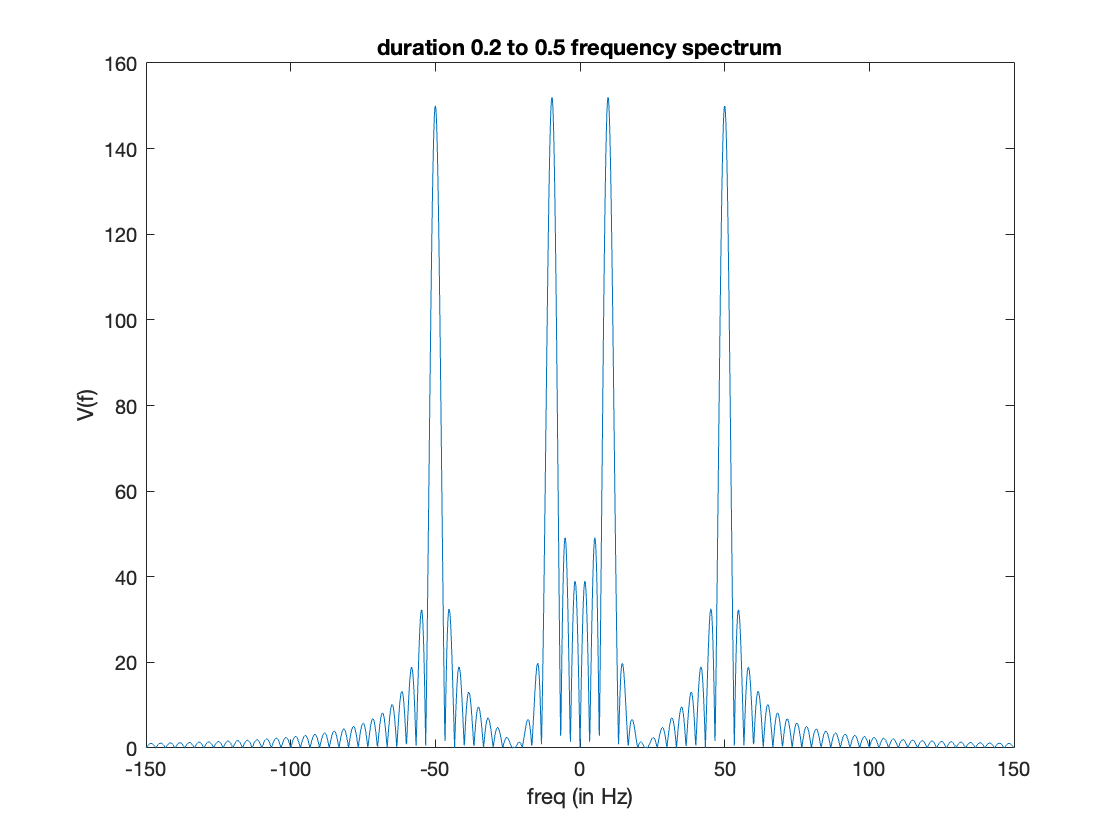


% (2) for duration 0.2sec to 0.5 sec

fft2 = fftshift(fft(nonStationary(0.2*Fs:0.5*Fs),8192));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fft2);

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1; 

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

%Plotting
plot(freq,abs(fft2));
title("duration 0.2 to 0.5 frequency spectrum");
xlabel("freq (in Hz)");
ylabel("V(f)");
xlim([-150,150]);

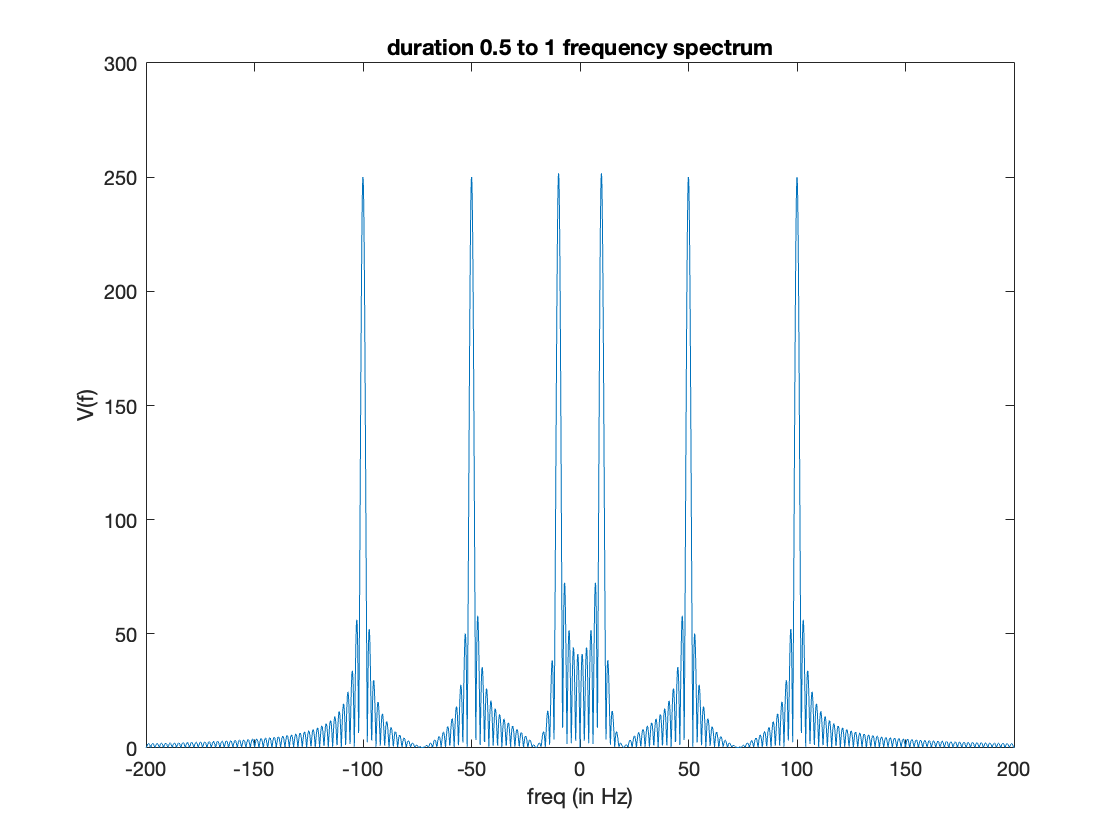


% (3) Sin(2𝛱*100*t)   0.5 sec < t < 1 sec and 0 for 0 < t < 0.5 sec

fft3 = fftshift(fft(nonStationary(0.5*Fs:end),8192));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fft3);  

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1; 

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

plot(freq,abs(fft3));
title("duration 0.5 to 1 frequency spectrum");
xlabel("freq (in Hz)");
ylabel("V(f)");
xlim([-200,200]);

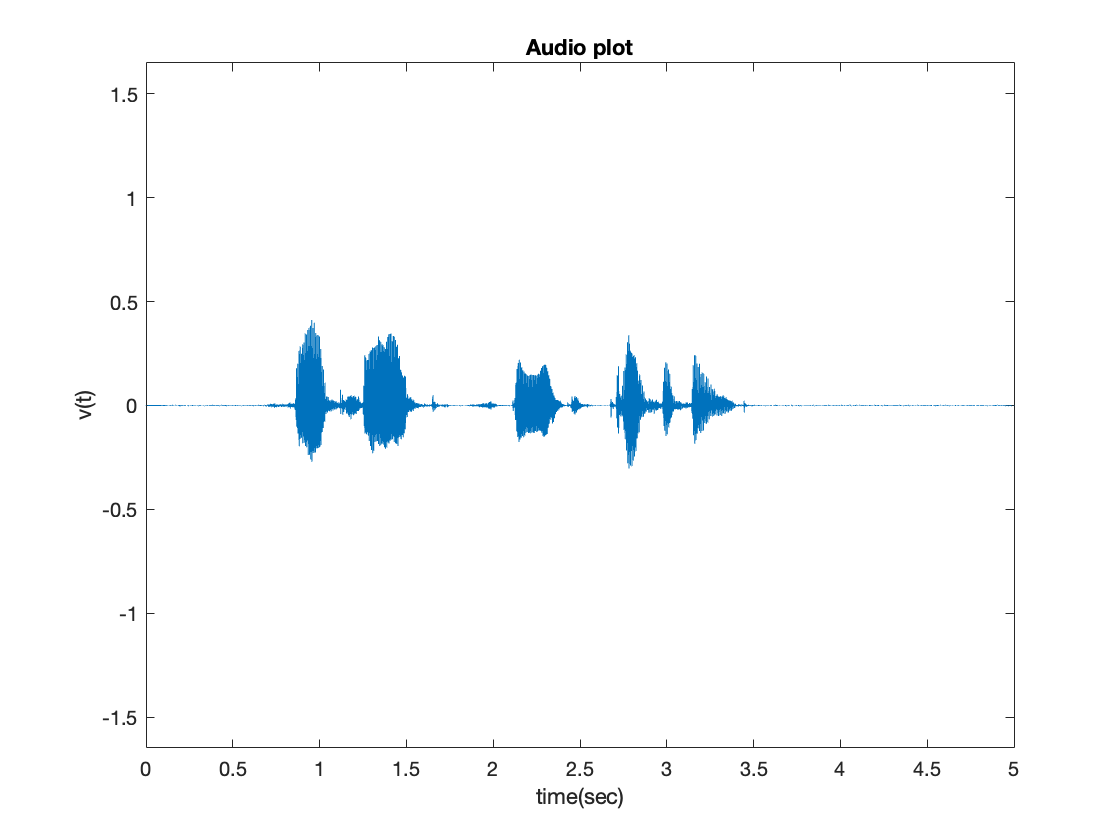

%%--------------------------------Part D ----------------------------------

%Reading the original recorded audiofile
[y,fs] = audioread('SaakshatSP.wav');

%time duration of the given audio file 
time_duration = length(y)/fs;

%re sampling frequency in Hz
Fs = 8000;

%using inbuilt resample function
y_new = resample(y,Fs,fs);

%generating the time axis
t = 0 : 1/Fs : time_duration - 1/Fs;

%plotting
plot(t,y_new);
ylim([-4*max(y_new) 4*max(y_new)]);
xlabel("time(sec)");
ylabel("v(t)");
title("Audio plot");

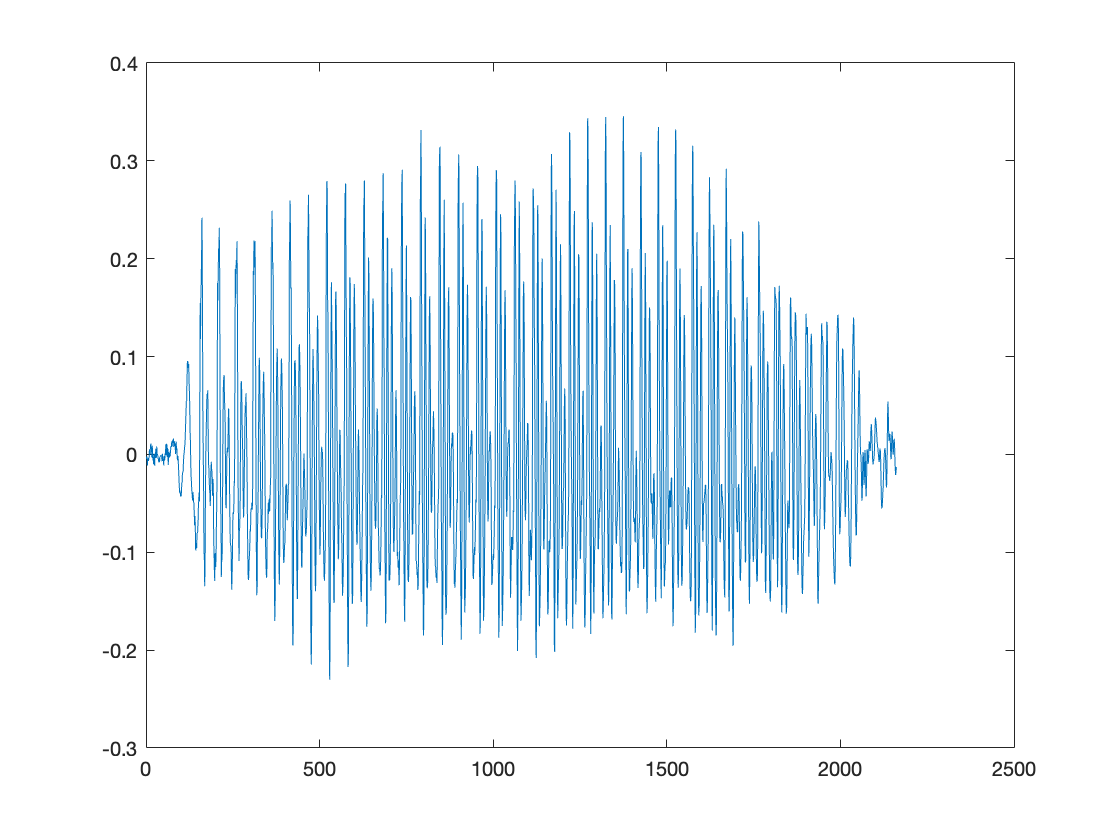


% (1) vowels 

%resampling frequency
Fs = 8000;

%Taking aa part from resampled audio file
aa_sound = y_new(1.24*Fs : 1.51*Fs);

plot(aa_sound);

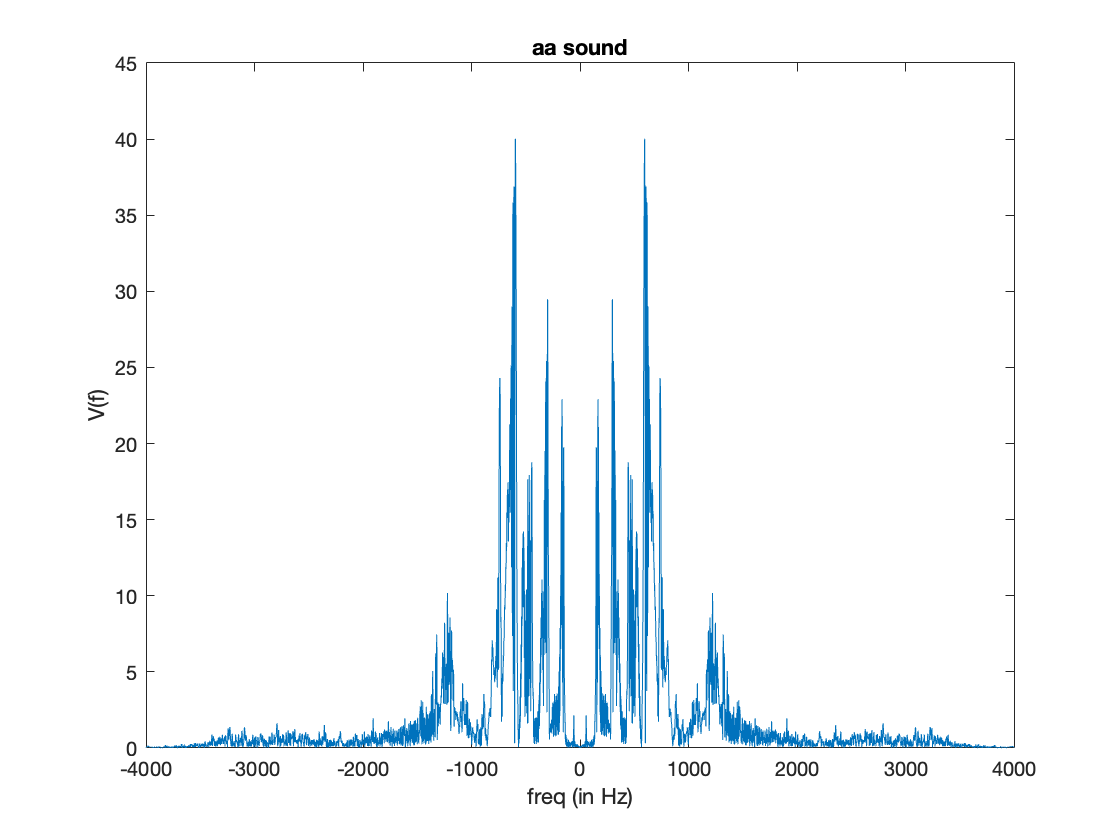


%Frequency domain plotting 
fft_aa = fftshift(fft(aa_sound,8192));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fft_aa);  

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1; 

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

%plotting
plot(freq,abs(fft_aa));
title("aa sound");
xlabel("freq (in Hz)");
ylabel("V(f)");

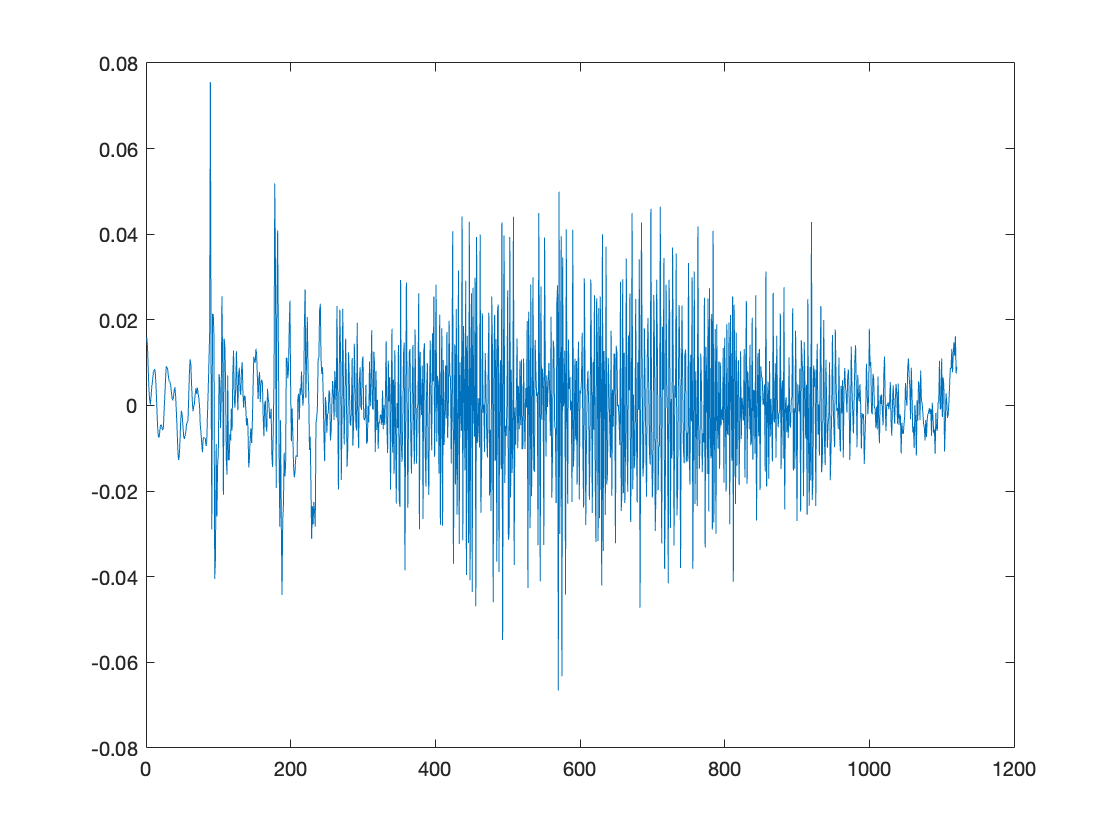

% (1) Sibilant sounds

%Taking sh part from resampled audio file
sh_sound = y_new(1.11*Fs : 1.25*Fs);

plot(sh_sound);

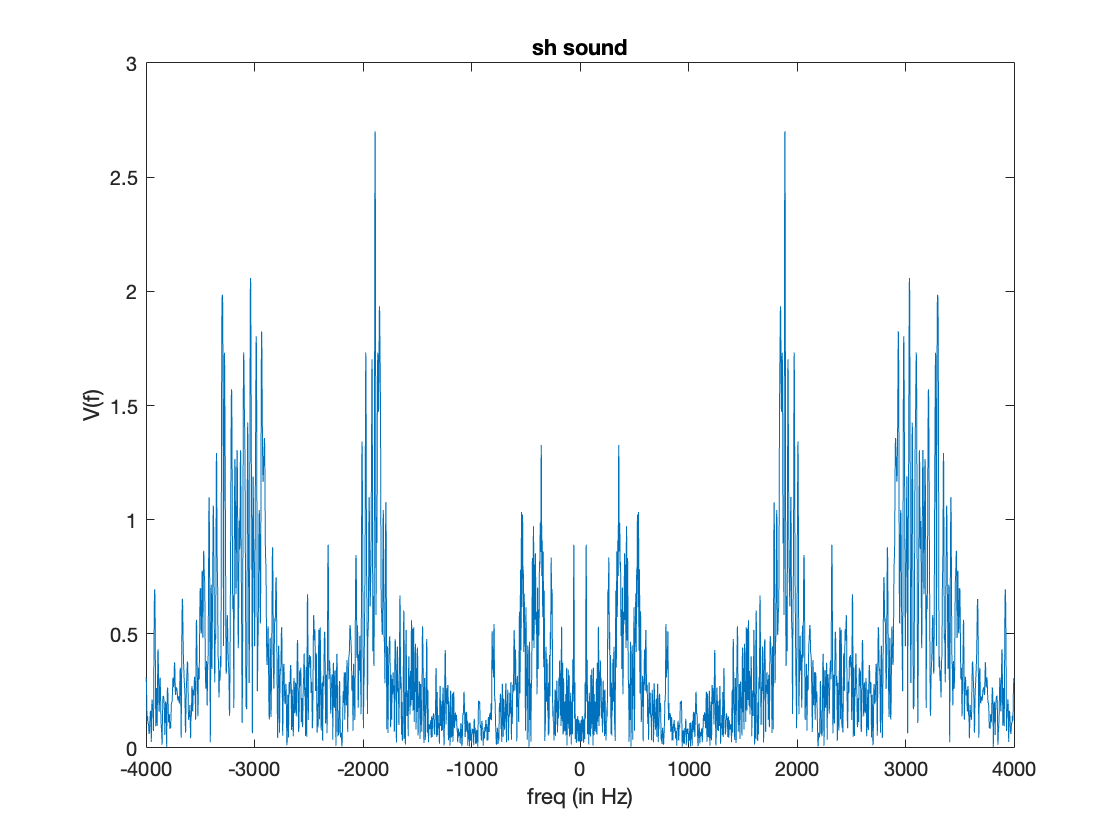


fft_sh = fftshift(fft(sh_sound,8192));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fft_sh);  

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1; 

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

%plotting
plot(freq,abs(fft_sh));
title("sh sound");
xlabel("freq (in Hz)");
ylabel("V(f)");

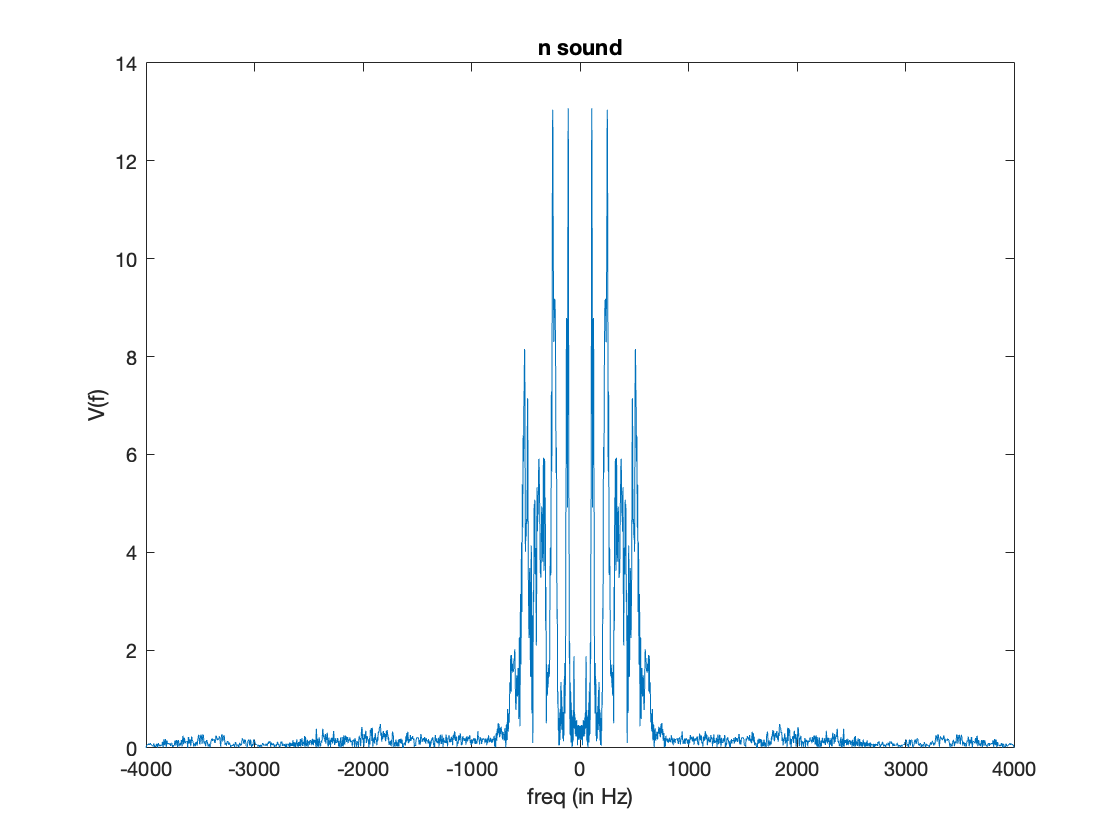


% (3) Nasal

%Taking n part from resampled audio file
n_sound = y_new(3.18*Fs : 3.38*Fs);

fft_n = fftshift(fft(n_sound,8192));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fft_n);  

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1; 

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

%plotting
plot(freq,abs(fft_n));
title("n sound");
xlabel("freq (in Hz)");
ylabel("V(f)");

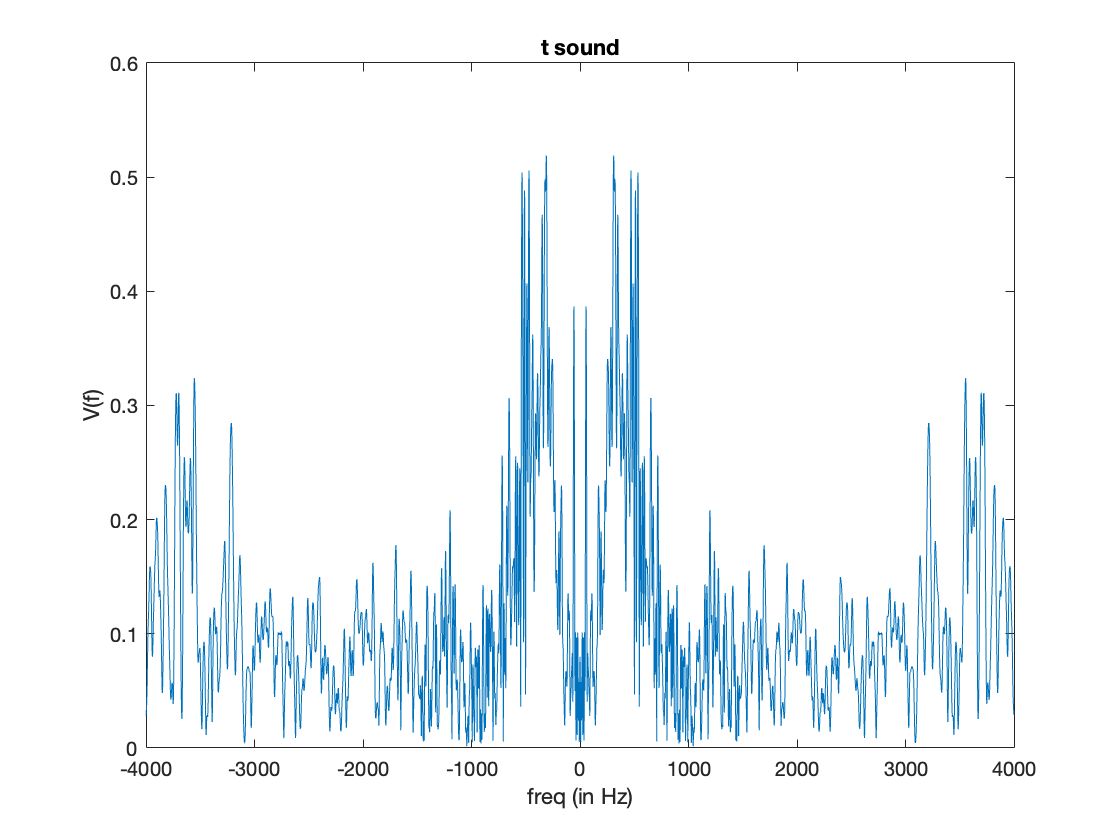


% (4) Unvoiced and unaspirated consonants

%Taking t part from resampled audio file
t_sound = y_new(1.6*Fs : 1.7*Fs);

fft_t = fftshift(fft(t_sound,8192));

%length of the FFT of non stationary signal in frequency domain
Len_f = length(fft_t);  

%iterating freq from -len/2 to +len/2
freq = -Len_f/2 : 1 : Len_f/2 - 1; 

%converting each term of freq into frequency as for the 'k'th term f = Fs.k/N 
freq = Fs*freq/Len_f; 

%plotting
plot(freq,abs(fft_t));
title("t sound");
xlabel("freq (in Hz)");
ylabel("V(f)");